% Supplemental program 5.2

% ---------------------------------------------------------
% Diurnal cycle of soil temperature with phase change using
% "excess heat" or "apparent heat capacity"
% ---------------------------------------------------------
% --- Physical constants in physcon structure
physcon.tfrz = 273.15;                         % Freezing point of water (K)
physcon.cwat = 4188.0;                         % Specific heat of water (J/kg/K)
physcon.cice = 2117.27;                        % Specific heat of ice (J/kg/K)
physcon.rhowat = 1000.0;                       % Density of water (kg/m3)
physcon.rhoice = 917.0;                        % Density of ice (kg/m3)
physcon.cvwat = physcon.cwat * physcon.rhowat; % Heat capacity of water (J/m3/K)
physcon.cvice = physcon.cice * physcon.rhoice; % Heat capacity of ice (J/m3/K)
physcon.tkwat = 0.57;                          % Thermal conductivity of water (W/m/K)
physcon.tkice = 2.29;                          % Thermal conductivity of ice (W/m/K)
physcon.hfus = 0.3337e6;                       % Heat of fusion for water at 0 C (J/kg)


% --- Initialize soil texture variables

% Soil texture classes (Cosby et al. 1984. Water Resources Research 20:682-690)

%  1: sand
%  2: loamy sand
%  3: sandy loam
%  4: silty loam
%  5: loam
%  6: sandy clay loam
%  7  silty clay loam
%  8: clay loam
%  9: sandy clay
% 10: silty clay
% 11: clay

soilvar.silt = [ 5.0, 12.0, 32.0, 70.0, 39.0, 15.0, 56.0, 34.0,  6.0, 47.0, 20.0]; % Percent silt
soilvar.sand = [92.0, 82.0, 58.0, 17.0, 43.0, 58.0, 10.0, 32.0, 52.0,  6.0, 22.0]; % Percent sand
soilvar.clay = [ 3.0,  6.0, 10.0, 13.0, 18.0, 27.0, 34.0, 34.0, 42.0, 47.0, 58.0]; % Percent clay

% Volumetric soil water content at saturation (porosity)
% (Clapp and Hornberger. 1978. Water Resources Research 14:601-604)

soilvar.watsat = [0.395, 0.410, 0.435, 0.485, 0.451, 0.420, 0.477, 0.476, 0.426, 0.492, 0.482];

% --- Model run control parameters

tmean = physcon.tfrz + 15.0;       % Mean daily air temperature for diurnal cycle (K)
trange = 10.0;                     % Temperature range for diurnal cycle (K)
dt = 1800;                         % Time step (seconds)
nday = 200;                        % Number of days
soilvar.soil_texture = 1;          % Soil texture class: sand
soilvar.method = 'excess-heat';    % Use excess heat for phase change

%soilvar.soil_texture = 11;         % Soil texture class: clay
%soilvar.method = 'apparent-heat-capacity'; % Use apparent heat capacity for phase change

% --- Initialize soil layer variables

% Number of layers in soil profile

soilvar.nsoi = 120;

% Soil layer thickness (m)

for i = 1:soilvar.nsoi
   soilvar.dz(i) = 0.025;
end

% Soil depth (m) at i+1/2 interface between layers i and i+1 (negative distance from surface)

soilvar.z_plus_onehalf(1) = -soilvar.dz(1);
for i = 2:soilvar.nsoi
   soilvar.z_plus_onehalf(i) = soilvar.z_plus_onehalf(i-1) - soilvar.dz(i);
end

% Soil depth (m) at center of layer i (negative distance from surface)

soilvar.z(1) = 0.5 * soilvar.z_plus_onehalf(1);
for i = 2:soilvar.nsoi
   soilvar.z(i) = 0.5 * (soilvar.z_plus_onehalf(i-1) + soilvar.z_plus_onehalf(i));
end

% Thickness between between z(i) and z(i+1)

for i = 1:soilvar.nsoi-1
   soilvar.dz_plus_onehalf(i) = soilvar.z(i) - soilvar.z(i+1);
end
soilvar.dz_plus_onehalf(soilvar.nsoi) = 0.5 * soilvar.dz(soilvar.nsoi);

## Initial soil temperature (K) and unfrozen and frozen water (kg H2O/m2)

for i = 1:soilvar.nsoi
   % Temperature (K)

   soilvar.tsoi(i) = physcon.tfrz + 2.0;

   % Soil water at saturation (kg H2O/m2)

   h2osoi_sat = soilvar.watsat(soilvar.soil_texture) * physcon.rhowat * soilvar.dz(i);

   % Actual water content is some fraction of saturation

   if (soilvar.tsoi(i) > physcon.tfrz)
      soilvar.h2osoi_ice(i) = 0;
      soilvar.h2osoi_liq(i) = 0.8 * h2osoi_sat;
   else
      soilvar.h2osoi_liq(i) = 0;
      soilvar.h2osoi_ice(i) = 0.8 * h2osoi_sat;
   end

end

% --- Time stepping loop to increment soil temperature

% Counter for output file

m = 0;


% Main loop is NTIM iterations per day with a time step of DT seconds.
% This is repeated NDAY times.
ntim = round(86400/dt);
for iday = 1:nday
   fprintf('day = %6.0f\n',iday)
   for itim = 1:ntim
      % Hour of day
      hour = itim * (dt/86400 * 24);
      % Surface temperature: Constant value TMEAN if TRANGE = 0. Otherwise, use a sine
      % wave with max (TMEAN + 1/2 TRANGE) at 2 pm and min (TMEAN - 1/2 TRANGE) at 2 am
      tsurf = tmean + 0.5 * trange * sin(2*pi/24 * (hour-8.0));
     % Thermal conductivity and heat capacity
      [soilvar] = soil_thermal_properties (physcon, soilvar);

      % Soil temperatures
      [soilvar] = soil_temperature (physcon, soilvar, tsurf, dt);

      % Save hourly soil temperature profile for last day
      if (iday == nday)
         % Surface output
         % Vector format - to write to data file
         m = m + 1;
         hour_vec(m) = hour;
         z_vec(m) = 0;
         tsoi_vec(m) = tsurf - physcon.tfrz; % deg C

         % For MATLAB contour
         hour_out(itim) = hour;
         z_out(1) = 0;
         tsoi_out(1,itim) = tsurf - physcon.tfrz; % deg C

         % Soil layers for top 100 cm
         for i = 1:soilvar.nsoi
            if (soilvar.z(i) > -1.0)
               m = m + 1;
               hour_vec(m) = hour;
               z_vec(m) = soilvar.z(i) * 100; % cm
               tsoi_vec(m) = soilvar.tsoi(i) - physcon.tfrz; % deg C

               z_out(i+1) = soilvar.z(i) * 100; % cm
               tsoi_out(i+1,itim) = soilvar.tsoi(i) - physcon.tfrz; % deg C
            end
         end
      end
   end
end

day =      1
day =      2
day =      3
day =      4
day =      5
day =      6
day =      7
day =      8
day =      9
day =     10
day =     11
day =     12
day =     13
day =     14
day =     15
day =     16
day =     17
day =     18
day =     19
day =     20
day =     21
day =     22
day =     23
day =     24
day =     25
day =     26
day =     27
day =     28
day =     29
day =     30
day =     31
day =     32
day =     33
day =     34
day =     35
day =     36
day =     37
day =     38
day =     39
day =     40
day =     41
day =     42
day =     43
day =     44
day =     45
day =     46
day =     47
day =     48
day =     49
day =     50
day =     51
day =     52
day =     53
day =     54
day =     55
day =     56
day =     57
day =     58
day =     59
day =     60
day =     61
day =     62
day =     63
day =     64
day =     65
day =     66
day =     67
day =     68
day =     69
day =     70
day =     71
day =     72
day =     73
day =     74
day =     75
day =     76
day =     77

## Make contour plot

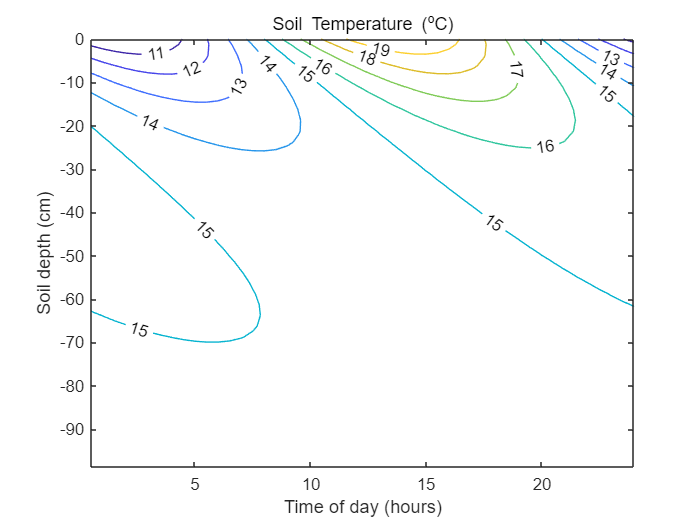

contour(hour_out,z_out,tsoi_out,'ShowText','on')
title('Soil Temperature (^oC)')
xlabel('Time of day (hours)')
ylabel('Soil depth (cm)')

## Write output file

A = [hour_vec; z_vec; tsoi_vec];
fileID = fopen('data.txt','w');
fprintf(fileID,'%12s %12s %12s\n','hour','z','tsoi');
fprintf(fileID,'%12.3f %12.3f %12.3f\n', A);
fclose(fileID);